*MAPS2001 project*

# Analysis of Atmospheric Stable Water Isotopes

## Abstract

*To be done later.*

## Introduction

Since 1970's, there has been an increased interest in investigation of fractionation of the isotopes occurring in the components of water, i.e. $H^2$, $H^3$ and $O^{18}$. Most of the studies of these complex interactions between different parts of the atmosphere are based on the world-wide survey organized since 1961 by the International Atomic Energy Ageney (IAEA) and the World Meteorological Organisation (WMO). The analysis of tritium abundance in different parts of the world can be related to proposing solutions to hydrological problems (e.g. predictions of lakes drought). Furthermore, using the data for concentration of hydrogen and oxygen isotopes, it is possible to deduce various characteristics of the circulation patterns and mechanism of the global and local movements of water. [1], [2]

Here, working with Global Network of Isotopes Precipitation (GNIP) database, three separate-steps analyses have been provided.

The network of stations was initially created in 1958 with the goal of detecting atmospheric fallout from nuclear tests during the Cold War. Following this original purpose, simple analysis of Valentia Observatory GNIP station data was conducted, visualising the simple trends and correlations in abundances of $H^2$, $H^3$ and $O^{18}$ in time.

Subsequently, reflecting the conversion of network in 1970's to support various hydrological studies, an attempt to validate the hypothesis of Lee et al. (2007) and visualise the results was made. It proposes possible correlation between climate and isotope concentration in precipitation, stating that the amount of deuterium per unit volume of precipitation linearly increases with the average annual temperature. This relationship, however, is said to hold only for regions with average annual temperatures of 15° or less, above this threshold, no correlation is observed.

Lastly, recent work [4] has looked at stable water isotopes and large-scale vertical motions in the tropics to propose reasons for large atmospheric circulation in this region. Following that, the specific graph of average deuterium abundance in precipitation for different intervals of monthly averages precipitation rates for East and West Pacific was reproduced from the paper. The aim was to produce and generalise the code which could be then further applicable to different regions as well.

[1] W. Dansgaard, Stable isotopes in precipitation,Tellus XVI (1964), 4 November 1964.

[2] https://en.wikipedia.org/wiki/Tritium

[3] J. Lee, I. Fung, D. DePaolo, C. Henning, Analysis of the global distribution of water isotopes using the NCAR atmospheric general circulation model, Journal of Geophysical Research, Vol 112, D16306,  2007

[4] G. Torri, D. Ma, Z. Kuang Stable water isotopes and large-scale vertical motions in the tropics, Journal of Geophysical Research: Atmospheres Volume 122, Issue 7, pages 3703-3717, 2017

## Computational Methodology

## **        1. Simple Initial Analysis of Data (Valentia GNIP Station)**

First, to understand the format and to visualize the data, the Valentia Observatory (Ireland) was randomly chosen. Simple analysis has been conducted – trends and correlations in abundances of $H^2$, $H^3$ and $O^{18}$ in time.

IAEA WISER data for Valentia GNIP station was downloaded and imported to MATLAB.

clear all
clf
v = 'valentia.xlsx';

Readtable function was used to easily extract data from the Excel file.

s = readtable (v); % reading data from the specific Data File

IAEA WISER GNIP date were found to be not in a chronological order. To easily manipulate the data in general, the sorting function had to be invented and used.

%%% sorts the data by date: %%%
allDates=s.Date(:); % gives all dates in one cell
A = datetime(allDates,'Format','yyyy-MM-dd'); % formats 'allDates' cell to an array datetime values

[sortDates,originalIndex]=sort(A); % sorts A array (708x1 - includes only dates) into ascending order
                                   % originalIndex gives the original index or s table

sortedS=s(originalIndex,:); % prints table with originalIndex, which gives data in ascending date

Saving measurements for deuterium, tritium and oxygen as variables:

% convenient labelling of variables
H2 = sortedS.H2;
H3 = sortedS.H3;
O18 = sortedS.O18;

Deuterium variance with respect to time:

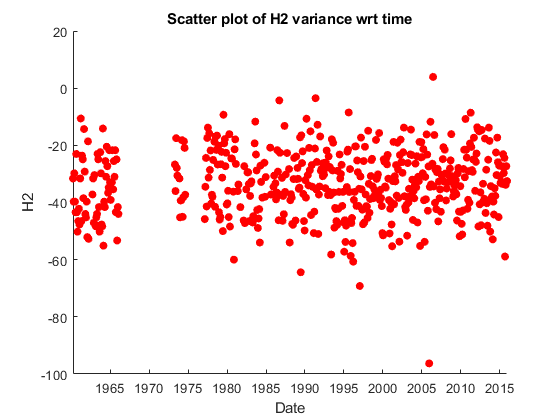

figure (1)
scatter (sortDates, H2, 'ro', 'filled');
datetick('x','yyyy','keeplimits');
xlabel ('Date');
ylabel ('H2');
title ('Scatter plot of H2 variance wrt time')

Similar scatter plots have been produced for tritium and oxygen.

## **        2. Comparison of Isotope Precipitation Rate to Average Annual Temperature Word-Wide and Visualising Possible Correlation**

## **        3. Reproduction and Generalisation of the Code for the Graph of Average Deuterium Abundance In Precipitation for Different Intervals of Monthly Averages Precipitation Rates**

To reproduce and generalise the code which could be then further applicable to different regions as well, the plot from page 3714: $\delta D$ vs. precipitation rate per day:

*[4] G. Torri, D. Ma, Z. Kuang Stable water isotopes and large-scale vertical motions in the tropics, Journal of Geophysical Research: Atmospheres Volume 122, Issue 7, pages 3703-3717, 2017*

was replotted.

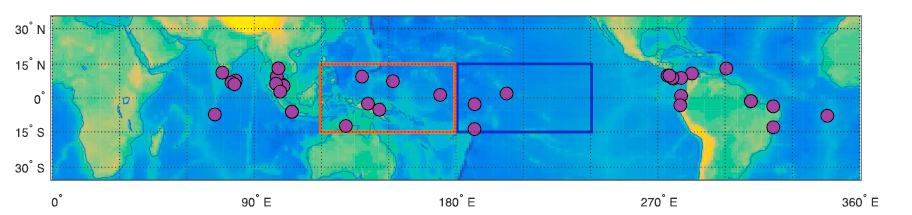

The data from IAEA WISED database for West and East Pacific was donwloaded accordingly:

**West:** (15° N - 15° S, 120° E - 180° E): Darwin, Jayapura, Madang, Tarawa, Truk, Yap

**East**: (15° N - 15° S, 180° E - 240° E): Apia, Canton Island, Christmas Island,

and imported to MATLAB. Readtable function was again used to easily extract data from downloaded Excel files, and the data was sorted chronologically using a sorting function (used in 1)).


clear all
clf
% WEST
wt1 = 'WDarwin.xlsx'; % Darwin
wt2 = 'WJayapura.xlsx'; % Jayapura
wt3 = 'WMadang.xlsx'; % Madang
wt4 = 'WTarawa.xlsx'; % Tarawa
wt5 = 'WTruk.xlsx'; % Truk
wt6 = 'WYap.xlsx'; % Yap

% EAST
et1 = 'EApia.xlsx'; % Apia
et2 = 'ECanton_Island.xlsx'; % Canton Island
et3 = 'EChristmas_Island.xlsx'; % Christmas Island
% % WEST
w1 = readtable (wt1);

w2 = readtable (wt2);

w3 = readtable (wt3);

w4 = readtable (wt4);

w5 = readtable (wt5);

w6 = readtable (wt6);


% EAST
e1 = readtable (et1);

e2 = readtable (et2);

e3 = readtable (et3);

To find general trends for these two areas (East and West), all data has to be concatenated first. To do this, the comment column was removed, as some of the downloaded station data had no data in this column, and so the column did not exist in the data when converted to a table. This only affected the data for West, so the comment column was removed from this data. However, when the section was run again without re-importing the western datasets, MATLAB did not understand the non-existence of this variable. Therefore, this process is done only if the data actually exists (if it exists for the first one, it is assumed that it exists for all).

A=any(strcmp('Comment',fieldnames(w1)));
B=any(strcmp('Comment',fieldnames(w2)));
C=any(strcmp('Comment',fieldnames(w3)));
D=any(strcmp('Comment',fieldnames(w4)));
E=any(strcmp('Comment',fieldnames(w5)));
F=any(strcmp('Comment',fieldnames(w6)));
ABCDEF=[A,B,C,D,E,F];
if any(ABCDEF) == 1
w1.Comment=[];
w2.Comment=[];
w3.Comment=[];
w4.Comment=[];
w5.Comment=[];
w6.Comment=[];
end

Also, some figures were set to refer back to a certain graph when specifying certain properties and data.

wFull=[w1;w2;w3;w4;w5;w6]; % concatenating the data from the various western stations
eFull=[e1;e2;e3]; % doing the same for east

figureNumScatter=10;
figureNumBins=20; 
% setting figure numbers for the two graphs

The loop was  used to plot the graphs twice, switching between East and West each time.

for j=[1,2]
 if j==1
     % for the Eastern Loop
     s=eFull;
     pointColour='xblack';
     barColour='blue';
     
 else
     % Western loop
     s=wFull;
     pointColour='.red';
     barColour='yellow';
     
 end

Next, the relevant data was retrieved. As the precipitation per day was supposed to be plotted, and months are different lengths, the number of days for the period when each reading was taken over was calculated, and this fact was further used to determine the average precipitation per day. Note that this had to be done via dividing total precipitation by number of days, as there was not any more temporal resolution than this.

% retrieving relevant data
d=datenum(s.Date,'yyyy-mm-dd');
H3=s.H3;
H2=s.H2;
O18=s.O18;

% days in month
numdays=(datenum(s.EndOfPeriod, 'yyyy-mm-dd')- datenum(s.BeginOfPeriod,'yyyy-mm-dd')+1);

% precipitation per day
pppday=s.Precipitation./numdays;

First, the scatter plot was plotted to visualize the unbinned data and to decide on the bin size.

% see a scatter plot of the data
figure(figureNumScatter)
hold on
plotObjectpppD(j)=plot(pppday,H2,pointColour);
title('Delta Deuterium vs. Precipitation Rate: Scatter plot')
hold off
xlabel('Precipitation rate (mm per day)')
ylabel('\delta D')

The original graph was plotted using bins of five with the final bin stretching to infinity.

% deciding our bin sizes
Edges=[0,5,10,15,20,Inf];

To do these steps,  the $\delta D$ data must have been discretized by its relevant precipitation per day data.

% finding out which deltaH2s fall in each ppt/day
[pppdaybin,Edge]= discretize(pppday,Edges);

% pppdaybin = which 'bin' each pppday in the array falls in
% to get the array of deltaH2 for each bin

Next, the loop was used in order to sparate out each binned set of data:

for i=1:(length(Edge)-1)
    
% using a structure as it is easier to use with loops
% making the struct separated by bin

H2binned(i).H2=H2(pppdaybin == i);
end

And another loop was used in order to find the means for each bin:

for i=1:(length(Edge)-1)
% finding the mean of these binned deltaH2 (along with the standard deviations)
    H2binned(i).mean = nanmean(H2binned(i).H2);
    H2binned(i).error = nanstd(H2binned(i).H2);
end

Whilst structures generally work more quickly with loops, arrays are slightly easier to do basic data manipulation with, so the data is was converted back into an array.

for i=1:(length(Edge)-1)
% switching these back to an array, so we can more conveniently use this data (ouside of loops)
    H2binnedmeans(i)=H2binned(i).mean;
    %here we use the standard error, as opposed to just the standard deviation of the dataset
    H2binnedmeanstandarderror(i)=(H2binned(i).error)./sqrt(length(H2binned(i).H2));
end

The original graph was reproduced plotting the mean $\delta D$ binned, versus the midvalue of each bin. Note that for the last bin, the first bins midvalue was added to the beginning of the last bins first edge.

To find the midvalue:

% getting an array of the midvalues and creating an array of the start and end points of each bin, and then mean them

MidEdge(1,:)=Edge(1:(length(Edge)-1));
MidEdge(2,:)=Edge(2:length(Edge));
MidEdge=mean(MidEdge);
% redefining the mid edge for the final bin
MidEdge(length(Edge)-1)=MidEdge(1)+Edge(length(Edge)-1);


Finally, the bar function was used to produce similar bars as in the original graph. For the bars to not overlay each other, their position was adjusted depending on which loop cycle the code is on.

% plotting the graph, and use 'bar' function to plot as bars (as in the original paper)

if j==1
% shifting the bars for the first loop (East) to the negative
    MidEdgeShift=-1;
else
% and the bars for the second loop (West) to the positive
    MidEdgeShift=1;
end 
% plotting a bar graph
figure(figureNumBins)

To make the plot look little 'prettier':

% including earlier calculated shift
pointPosn=MidEdge+MidEdgeShift;
hold on

% creating a bar object so we can edit its properties
b(j)=bar(pointPosn,H2binnedmeans);

% adjust its width to allow us to see both bars at once, 
% and differentiate the colours we picked earlier
b(j).BarWidth=0.4;
b(j).FaceColor=barColour;
% to include errors, so we create an error bars object, and plot on the same graph
e=errorbar(pointPosn,H2binnedmeans,H2binnedmeanstandarderror);
% We remove the line and points of this 'second' graph, as we only want the error bars
e.LineStyle='none';
e.Marker='none';


At the end, all necessary details for the graph (title, axes labels, etc.) were included.

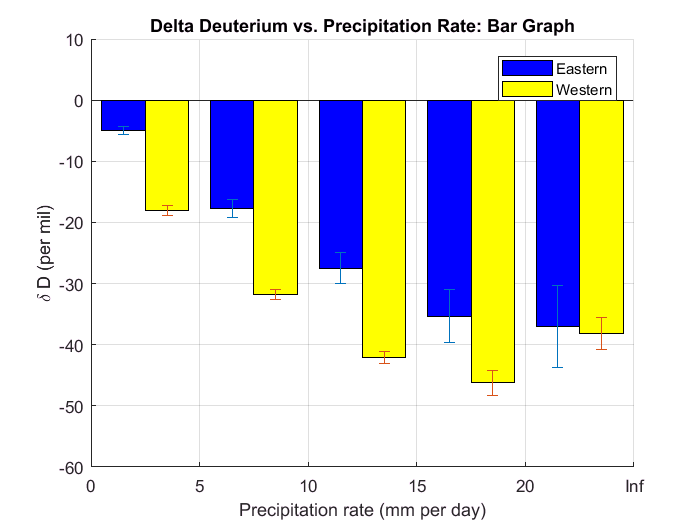

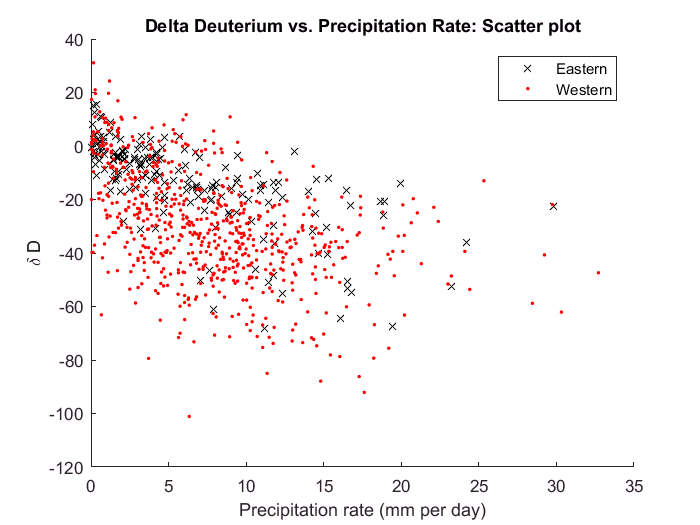

title ('Delta Deuterium vs. Precipitation Rate: Bar Graph')

xlabel('Precipitation rate (mm per day)')
ylabel('\delta D (per mil)')
xticklabels(Edges)
xlim([0,25])
ylim([-60,10])
grid on
hold off

end
legend (b,'Eastern', 'Western', 'Location', 'northeast' )
legend (plotObjectpppD,'Eastern', 'Western')

The next step was to repeat the same analysis for other isotopes, the UK and other geographic regions, i.e. Ireland.

The similar code was used, in a separate function file, to produce similar results for the UK, and identify any similar trends; however, as the UK lies in a different climate zone, some differences are expected to be seen.

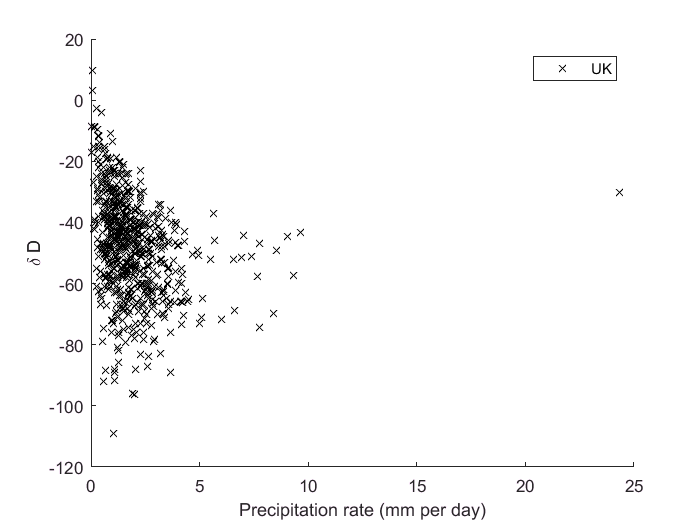

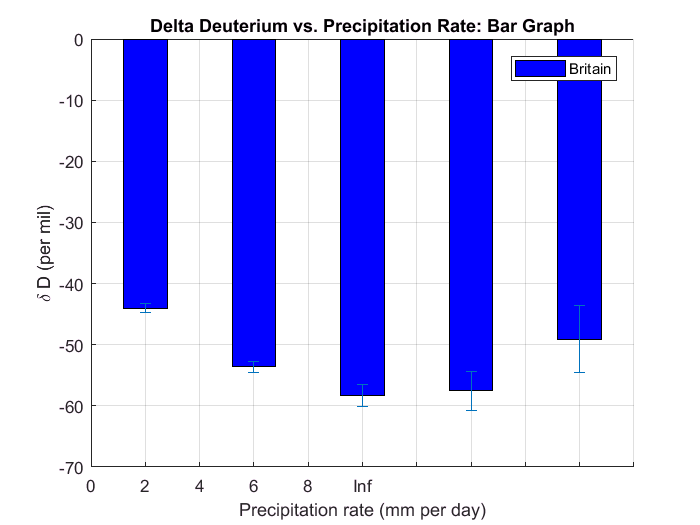

ukgraphsfunction('GeographicUK.xlsx');

Finally, the larger of the British Isles (Britain and Ireland) were compared to see if there were any significant differences, potentially due to geographic positioning.

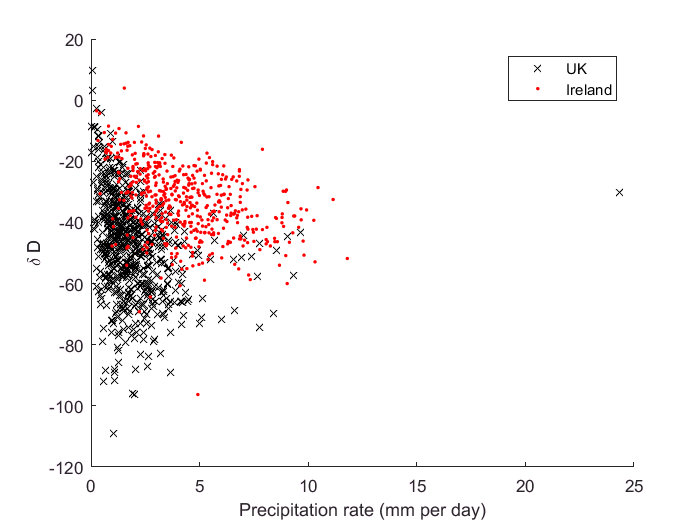

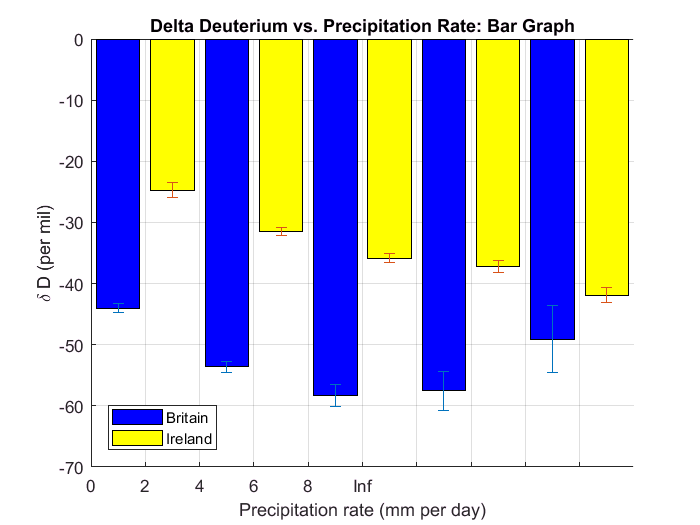

BIgraphsfunction('GeographicUK.xlsx','Ireland.xlsx')

## Critical Discussion of Results

## **        1. Simple Initial Analysis of Data (Valentia GNIP Station)**

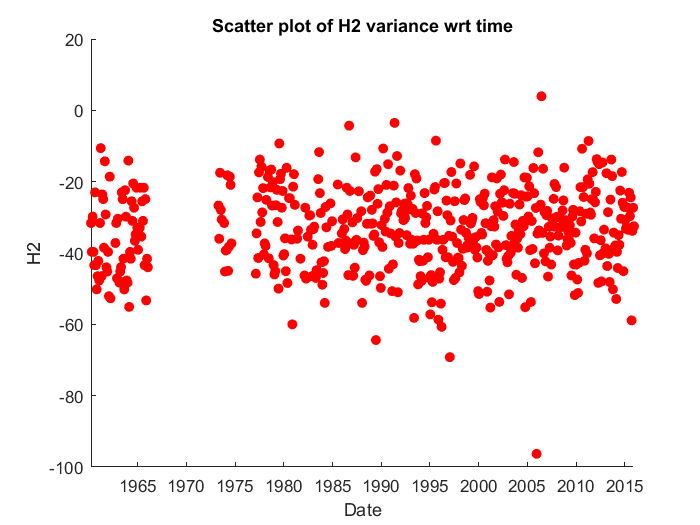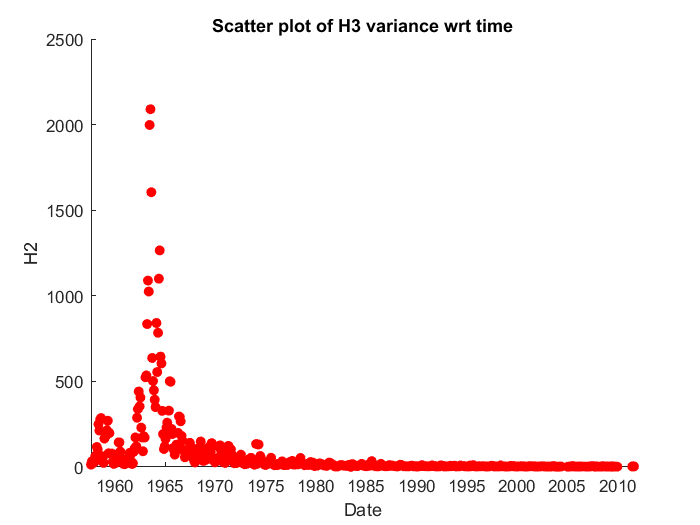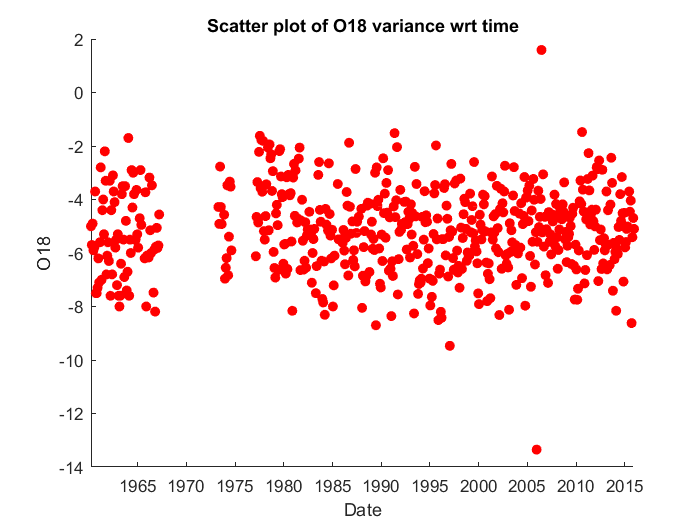

Discussion:

Plotting abundances of $H^2$ and $O^{18}$ with respect to time, a stable trend can be observed with a few potential outliers in 2005. Missing data around 1970 causes the gap seen in the graph.

For deuterium and oxygen 18:

- abundances of deuterium and oxygen 18 stable; potential outliers in 2005

- Valentia 2005: warmest and wettest place in Ireland  - correlation?

- possible future work to provide thorough analysis of deuterium and oxygen abundances dependence on temperature

- missing data in late sixties and early seventies

For the abundance of tritium, completely different trend is visualised. There is a non-standard peak around 1965. This follows the original purpose of the network of stations to detect atmospheric fallout from nuclear tests during the Cold War as tritium is an essential to the type of fusion used in weapons (https://en.wikipedia.org/wiki/Nuclear_weapon_design#Tritium_production)- Thus a rapid increase of the abundance of tritium in the atmosphere reflects the nuclear testing during Cold War.

H3:

- obvious trend: nonstandard and very high abundance of tritium around 1965

- detecting atmospheric fallout from nuclear tests during the Cold War

- tritium production is an essential to the type of fusion used in weapons (https://en.wikipedia.org/wiki/Nuclear_weapon_design#Tritium_production)

- thus a rapid increase of the abundance of tritium in the atmosphere

## **        2. Comparison of Isotope Precipitation Rate to Average Annual Temperature Word-Wide and Visualising Possible Correlation**

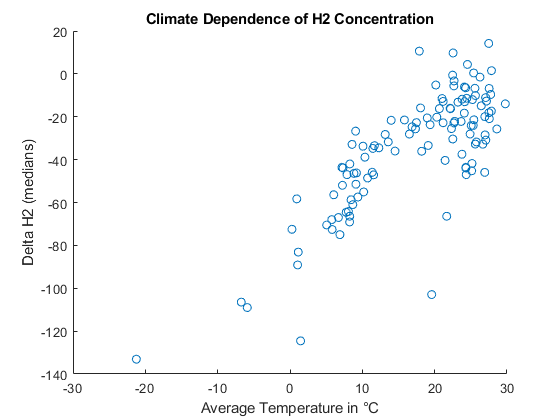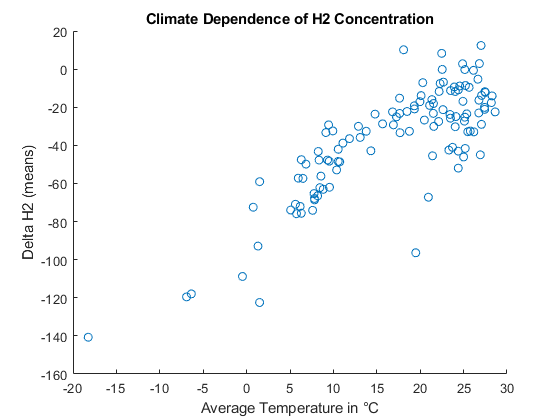

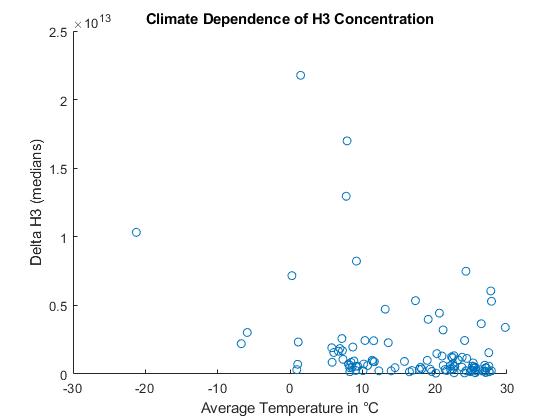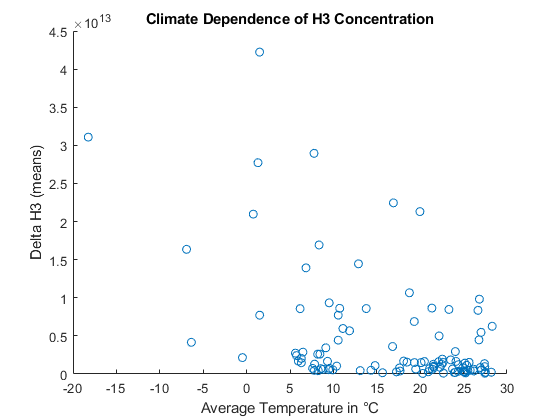

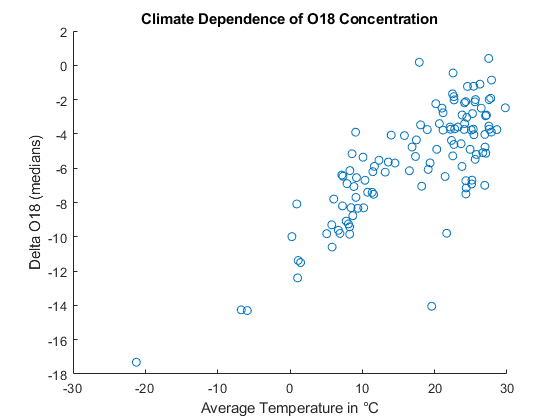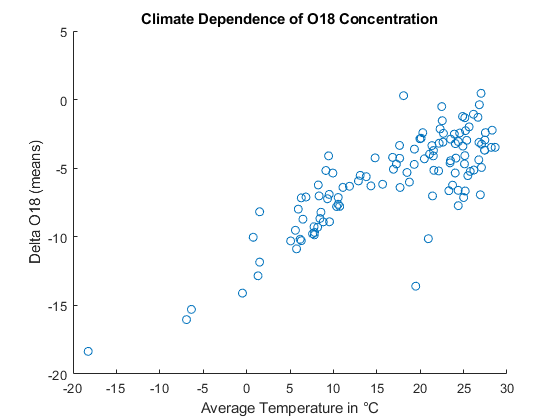

The so far produced scatterplots look like they validate the correlation described in the reference, although the variance seems quite high. This stems from the measures we took to simplify our task: 

- While the Isotope values are recorded at usually only a few locations per country the average temperature is given for the whole country - should we use the climate data given in the GNIP files?

- We neglected the size of the countries and summarised each one to one data point, which causes large errors for countries like the USA or Russia, that potentially span several climate zones -for increased precision, data should be grouped in smaller bins or by climate zone

- The annual temperature is (with a few exceptions) averaged over 30 years between 1960 and 1990, while part of measurements are from recent decades. Maybe climate change distorted the relationship under these conditions

- Some countries have stations in locations that are allocated to a certain country in the GNIP database and therefore went into our calculations for this country, although they geographically lie in an entirely different climate zone (example: Saint Helena in the South Altlantic Ocean provides misleading measurements for a 'UK climate')

What does this correlation stem from? The paper expresses the theory that the isotopes precipitate easily in warm environments. By the time the atmospheric water reaches colder regions like the artic/antarctic, there is simply no isotopes left to precipitate.  (*This is not the full discussion, after the coding part of the section is completed we will compare our results carefully to the paper and explain phenomena)*

Why is there no correlation found for Tritium?

Tritium is naturally only present in extremely small quantities in the atmosphere ($R_{\text{VSMOW}} =1\ldotp 85\pm 0\ldotp 36\times {10}^{-11} \text{ }\text{ppm}$), so the smallest contamination by human caused atomic activity can alter the natural patterns significantly.

## **        3. Reproduction and Generalisation of the Code for the Graph of Average Deuterium Abundance In Precipitation for Different Intervals of Monthly Averages Precipitation Rates**

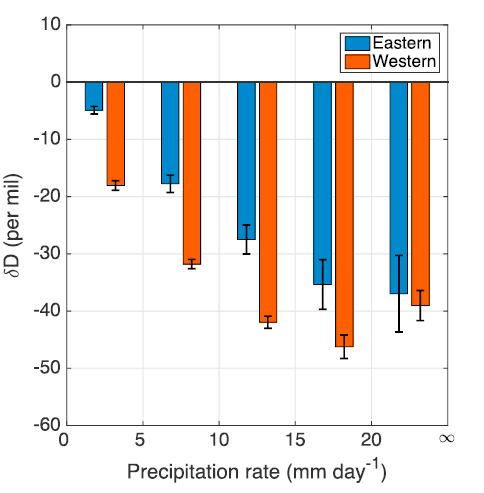

Our reproduced graph was very similar

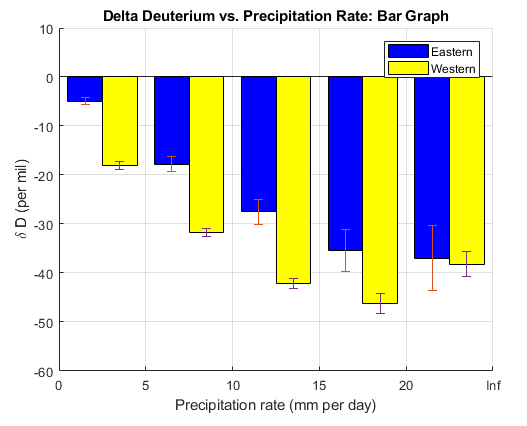

In tropics, the concentration of the isotopes has a negative correlation with the amount of precipitation that falls and is termed “amount effect”. This is largely due to isotopic depletion as the condensation progresses [3]. It was found that vertical structures vary greatly from one geographic region to another.

Interestingly, Eastern and Western Pacific have a different vertical structures. Although the whole region was believed to have top heavy profile, recent studies showed that Eastern pacific is more bottom heavy

Whilst the graphs are slightly different, this is only due to layout and sizing differences, and the actual data represented by them is the same. Interestingly, this is despite the original paper using a reduced date range, in order to use other datasets along with it. Therefore, it suggests that the authors of the paper may not have reduced the date range for plotting these bar graphs.

If we consider the equivalent graphs for the British Isles:

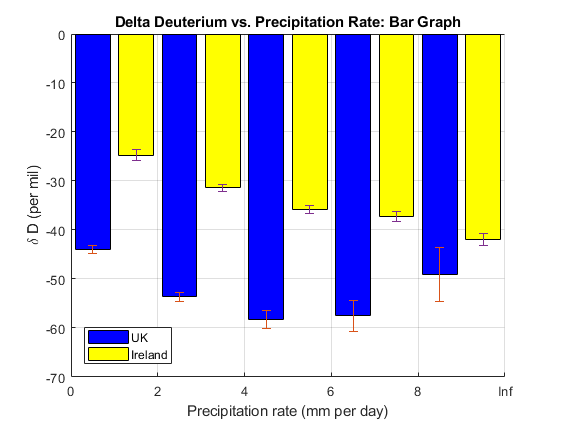

We can identify some major differences with the data from the tropical regions- the minima of $\delta D$ is at a lower precipitation rate (the bin 4-6mm per day for Britain versus the bins >15mm per day for the tropical regions), and is itself lower than in the tropics. This suggests there is a greater 'amount effect' in the UK than the tropics. Looking at the comparison with Ireland, we see the difference is similar; a lower, and earlier minima for the UK than Ireland. This suggests a more bottom heavy atmosphere in Ireland; the reasons for this are unclear.

## Conclusions and Future Work

**Conclusions**: *To be completed*

In part 3, we successfully reproduced a graphical representation of the data similar to one in our original research paper. This was then used to analyse the datasets from the UK and Ireland, and compare them, identifying key differences and preliminary discussion of the root causes for these climatological differences. We saw that, when considering the British Isles as a whole, and looking at $\delta D\text{ }$versus precipitation per day, there was a significant difference to the profile of the tropics, with the minima of $\delta D$being more negative and occuring at a lower precipitation rate than in the ropics. We hypothesised that this data suggested a more top heavy atmosphere over the British Isles, however this could have been due to other factors that we are unaware of. We also saw that, within the British Isles, Ireland had data that sugested a more bottom heavy profile than Britain. We were unsure of why this would be the case, however possible explanations include the fact that the prevailing winds across the British Isles are usually from the West/South-West, and so generally pass over Ireland before Britain. This leads to Ireland having a higher average rate of precipitation per day, as the moist air flowing in from the Atlantic will begin to precipitate as it rises on impact with the landmass of Ireland.This thus may shift the data for Ireland, leading to the appearance of a comparatively more bottom heavy region.

**Future work:**

- include the investigation of the data sets from tropics for Tritium and Oxygen 18 isotopes

- for Valentia and other areas: provide thorough analysis of deuterium and oxygen abundances dependence on temperature

For project part 2)Temperature Dependence:

Check whether GNIP temperatures provide a smaller variance for the correlation

Plot only the temperature range where the relationship holds (<15°C) and plot a line of best fit. Determine the variance. 

Use the mapping toolbox to visualise both datasets (Isotope concentration and temperature) on a world map. Reproduce the map from the reference where the difference between relative temperature and relative Isotope concentration is depicted. (Might not have time for this, would be future work) Determine regions beside the tropics where the correlation does not hold.

Following from the work done in part 3) a major area of future development would be to look at increasing the spatial resolution of our datasets across the geographic regions we are interested in (in this case the British Isles), as we currently have the data from all of the stations in the geographic area collected together. This does not allow us to see the differences in the microclimates across the area, and so we do not receive a distinct picture of the isotopic profile of these regions. Therefore, a future avenue of exploration would be to re-separate the collection stations' data, and consider the isotope profiles across the British Isles in as much spatial resolution as possible. This would potentailly lead to a better comparison of results, and allow us to better judge the geographic trends, and promote a better analysis of the causes of the varying isotopic profiles. 

In a similar vein, this section only considered the relationships between $\delta D$ and average precipitation rate per day. A wider comparison taking into account multiple variables such as wind speed/direction and pressure would allow a more nuanced view of the factors correlating with the variances in $\delta D$, allowing greater confidence in conclusions, and potentially allowing a better model of isotopic effects in the atmosphere to be created. Additionally, we have only considered deuterium in these representations, however this could be expanded to include isotopes of oxygen, and also tritium (although, due to its sensitivity to human actions, commented on in part 2, tritium may be less suitable for analysis of climatological effects), and note differences/similarities of the trends in these.

The larger overall step would be to use these techniques to analyse the isotope profiles of multiple countries, eventually being able to consider the spread of data across the entire world (or, at least those areas with an ongoing isotope collection station that reports data to the database used for these calculations), and its climate regions. This would allow comparison and consideration between differing and similar climatological areas. These steps would thus ultimately allow an increased depth of modelling and analysis of the total atmosphere, potentially enabling greater accuracy of forecasting, which is a vital application in the modern society.

**References:**

[1] W. Dansgaard, Stable isotopes in precipitation,Tellus XVI (1964), 4 November 1964.

[2] [https://en.wikipedia.org/wiki/Tritium](https://en.wikipedia.org/wiki/Tritium)

[3] Carol Kendall and Eric A. Caldwell, [Isotope Tracers in Catchment Hydrology](http://wwwrcamnl.wr.usgs.gov/isoig/isopubs/itchinfo.html) (1998), (Eds.)Elsevier Science B.V., Amsterdam. pp. 51-86.

[4] J. Lee, I. Fung, D. DePaolo, C. Henning, Analysis of the global distribution of water isotopes using the NCAR atmospheric general circulation model, Journal of Geophysical Research, Vol 112, D16306,  2007

[5] G. Torri, D. Ma, Z. Kuang Stable water isotopes and large-scale vertical motions in the tropics, Journal of Geophysical Research: Atmospheres Volume 122, Issue 7, pages 3703-3717, 2017

[6] Met Eireann’s end of year report: [https://www.met.ie/publications/met_ar2005.pdf](https://www.met.ie/publications/met_ar2005.pdf)

[7]  [https://en.wikipedia.org/wiki/Nuclear_weapon_design#Tritium_production](https://en.wikipedia.org/wiki/Nuclear_weapon_design#Tritium_production)

[8] Begemann & Libby (1957)

[9] Radioactive Aerosols. A. C. Chamberlain. 2004. 

[10] World Bank Group Climate Change Knowledge Portal [http://sdwebx.worldbank.org/climateportal/index.cfm?page=downscaled_data_download&menu=historical](http://sdwebx.worldbank.org/climateportal/index.cfm?page=downscaled_data_download&menu=historical)

[11] GNIP homepage [http://www-naweb.iaea.org/napc/ih/IHS_resources_gnip.html](http://www-naweb.iaea.org/napc/ih/IHS_resources_gnip.html)